clc
clear
A = [25 5 1 ;64 8 1;144 12 1];
B = [106.8 ;177.2 ;279.2];
Answer = gauss(A,B);
syms t V(t);
V(t) = 0;
n = length(B);
for i = 1 : n
    V(t) = V(t) + Answer(i)*t^(n-i);
end
fprintf('V1 = %d',vpa(V(10)));

V1 = 227

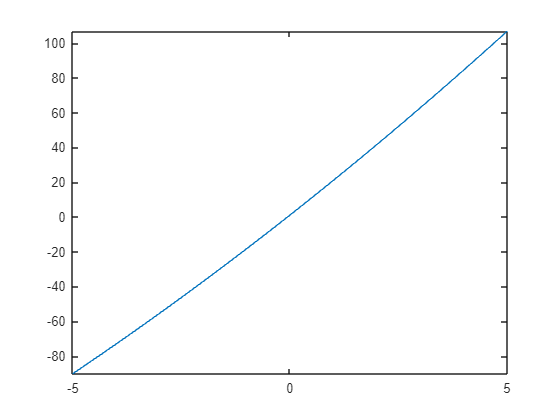

fplot (V(t));

function output = gauss(A,B)
n = length(B);
AOB = [A B];
Answer = zeros(n,1);
for i = 1 : n
    for j = i+1 : n
        ratio = AOB(j,i) / AOB(i,i);
        AOB(j,:) = AOB(j,:) - ratio*AOB(i,:);
    end
end
for i = 1 : n
    B(i) = AOB(i,n+1);
end
for i = n : -1 : 1
    Answer(i) = B(i);
    for j = i+1 : n
        Answer(i) = Answer(i) - AOB(i,j)*Answer(j);
    end
    Answer(i) = Answer(i)/AOB(i,i);
end
output = Answer;
end